## Regression Pulse width to $\omega$

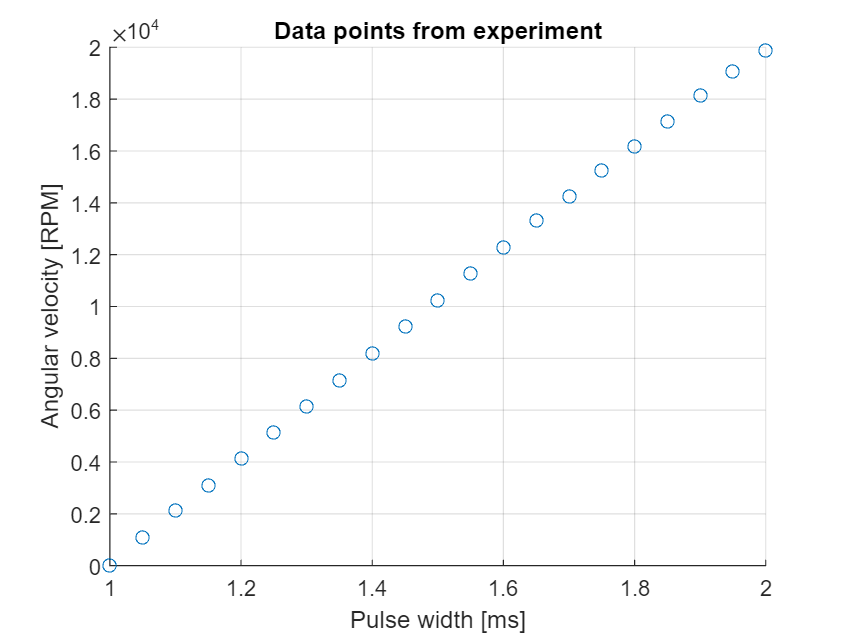

clear;
clc;
data = readmatrix("Data/Duty_To_RPM.csv");

figure()
scatter(data(:,1),data(:,2))
grid on
title('Data points from experiment')
xlabel("Pulse width [ms]")
ylabel("Angular velocity [RPM]")
saveas(gcf,'Images/Duty_To_Omega_Data','epsc')


$$\omega = \frac{2\pi}{60}RPM$$


omega = data(:,2)*pi/60;
duty_cycle = data(:,1) - 1;

[fitresult, gof] = createFit(duty_cycle,omega)

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =        1059  (1054, 1064)
       p2 =           0  (fixed at bound)

gof = struct with fields:
           sse: 825.2178
       rsquare: 0.9996
           dfe: 20
    adjrsquare: 0.9996
          rmse: 6.4235


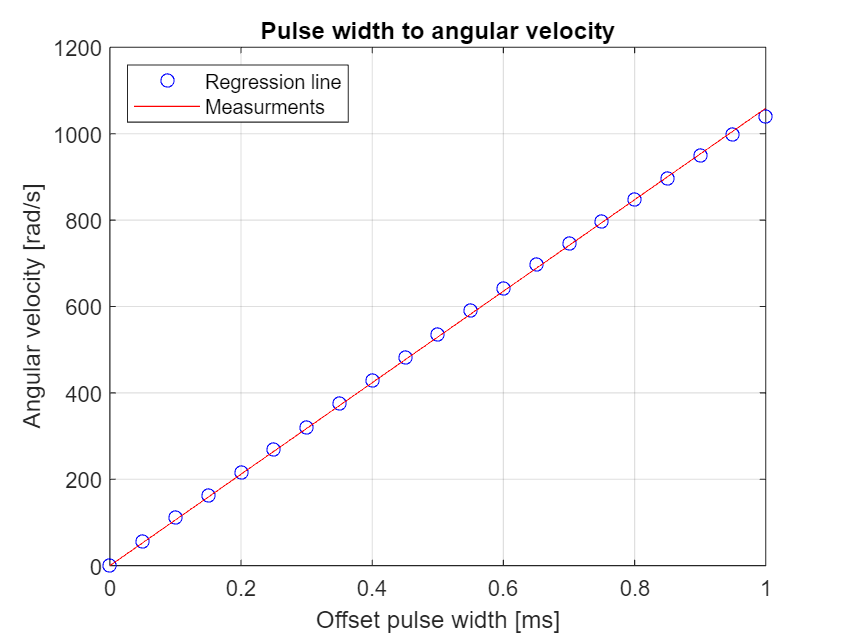


plot( fitresult,'r-', duty_cycle, omega,'bo' );
grid on
title('Pulse width to angular velocity')
ylabel('Angular velocity [rad/s]');
xlabel('Offset pulse width [ms]')
legend('Regression line','Measurments','location','northwest')
saveas(gcf,'Images/Duty_To_Omega_Reg','epsc')


inputConstant = 1059;

## Regression $\omega$ to Force

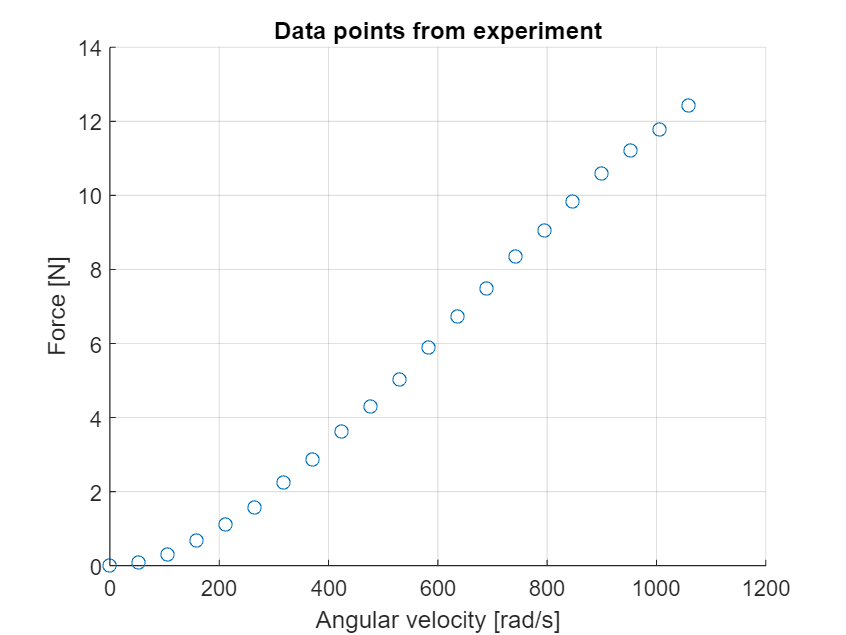

kt_data = readmatrix("Data/Kt_data.csv");

PWM_kt = kt_data(:,1)-1;
omega_kt = PWM_kt*inputConstant;
Weight = kt_data(:,2);
Force = Weight/1000 * 9.82;

scatter(omega_kt, Force)
grid on
title('Data points from experiment')
xlabel("Angular velocity [rad/s]")
ylabel("Force [N]")
saveas(gcf,'Images/Omega_To_Force_Data','epsc')


[fitresult, gof] = createFit(omega_kt,Force)

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     0.01101  (0.0104, 0.01163)
       p2 =           0  (fixed at bound)

gof = struct with fields:
           sse: 13.8671
       rsquare: 0.9613
           dfe: 20
    adjrsquare: 0.9613
          rmse: 0.8327


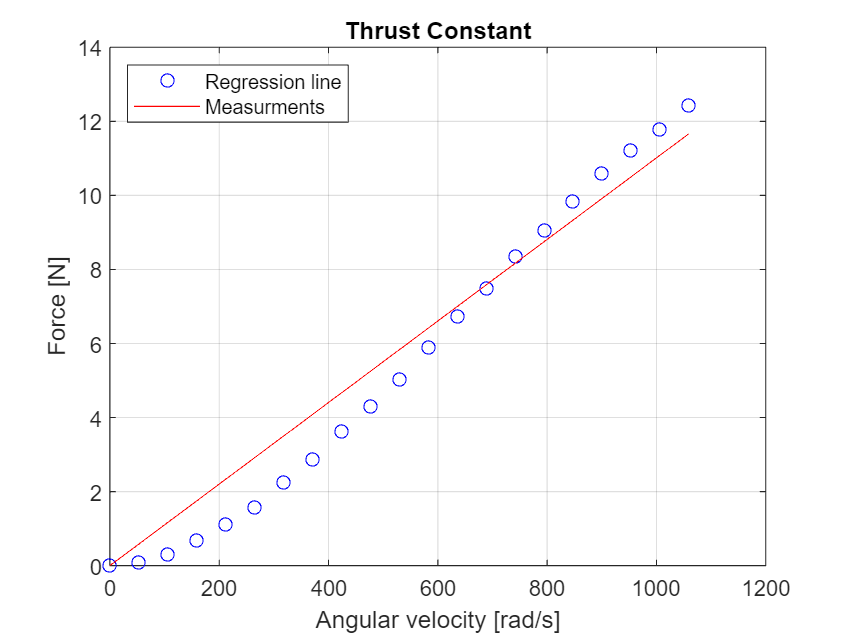


plot( fitresult,'r-', omega_kt, Force,'bo' );
grid on
title('Thrust Constant')
xlabel('Angular velocity [rad/s]');
ylabel('Force [N]')
legend('Regression line','Measurments','location','northwest')
saveas(gcf,'Images/Omega_To_Force_Reg','epsc')